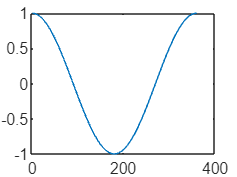

final=360;
no_of_itr=13;
word_length=64;
frac_length=54;
sign=1;
for i=1:final

    [cos_(i),sin_(i),o_z(i)]=cordic_f('cos_sin',1,1,i,no_of_itr,word_length, ...
        frac_length,sign);
end

for i=1:final
    
    [root(i),dummy,tan_inv(i)]=cordic_f('tan_inv',1,-180+i,i,no_of_itr,word_length,frac_length,sign);
end
x=fi(cos_,sign,word_length,frac_length);

plot(1:final,x)

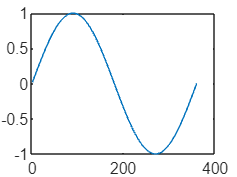

plot(1:final,sin_)


% 
% plot(1:final,cos((1:final).*pi/180))
% plot(1:final,o_x)
% o_x=o_x';
% x_exactly=cos((1:final).*pi/final)';
% error=max(abs(x_exactly-o_x));